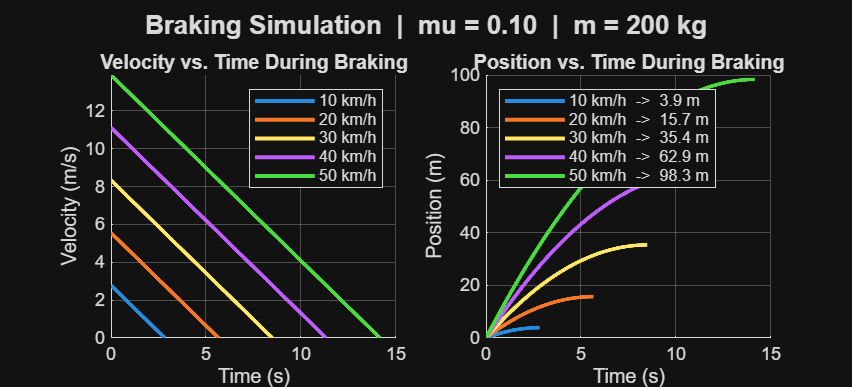

% =========================================================
%  Vehicle Braking Distance Simulator
%  Module 2 - Week 4 Project

clear; clc; close all;

%% -- 1. USER INPUT (tunable parameters) ------------------

m = input('  Enter vehicle mass [kg]: ');
while ~isnumeric(m) || ~isscalar(m) || m <= 0
    fprintf('  Invalid input. Please enter a positive number.\n');
    m = input('  Enter vehicle mass [kg]: ');
end

mu = input('  Enter friction coefficient (between 0 and 1.2): ');
while ~isnumeric(mu) || ~isscalar(mu) || mu <= 0 || mu > 1.2
    fprintf('  Invalid input. Please enter a value between 0 and 1.2.\n');
    mu = input('  Enter friction coefficient: ');
end

v0_kmh = input('  Enter speeds [km/h]: ');
while ~isnumeric(v0_kmh) || isempty(v0_kmh) || any(v0_kmh <= 0) || length(v0_kmh) > 8
    fprintf('  Invalid input. Enter a non-empty vector of positive values (max 8).\n');
    v0_kmh = input('  Enter speeds [km/h]: ');
end
v0_kmh = sort(v0_kmh);   % sort ascending for clean plots
v0     = v0_kmh / 3.6;   % convert to m/s


% -- Fixed simulation settings ----------------------------
g       = 9.81;    % gravitational acceleration [m/s^2]
dt      = 0.001;   % timestep [s]
t_max   = 30;      % maximum simulation time [s]

%% -- 2. PRE-ALLOCATE STORAGE -----------------------------

num_speeds   = length(v0);
stop_dist    = zeros(1, num_speeds);   % final stopping distance [m]
stop_time    = zeros(1, num_speeds);   % time to stop [s]

%% -- 3. TIME-STEPPED SIMULATION LOOP ---------------------

% Braking deceleration magnitude (constant, kinetic friction model)
%   F_brake = mu * m * g
%   a       = -F_brake / m = -mu * g
a_brake = -mu * g;   % [m/s^2]  (negative = deceleration)

% Colours for plotting - one per speed, generated dynamically
color_mat = lines(num_speeds);
colors = num2cell(color_mat, 2);   % convert rows to cell array of RGB triples

figure('Name','Braking Distance Simulator','NumberTitle','off', ...
       'Position',[100 100 1100 500]);

% -- Subplot 1: velocity vs. time -------------------------
subplot(1,2,1); hold on; grid on;
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity vs. Time During Braking');

% -- Subplot 2: position vs. time -------------------------
subplot(1,2,2); hold on; grid on;
xlabel('Time (s)');
ylabel('Position (m)');
title('Position vs. Time During Braking');

for i = 1:num_speeds

    % Initialize state
    v = v0(i);      % current velocity [m/s]
    x = 0;          % current position [m]
    t = 0;          % current time [s]

    % Storage for this run
    v_hist = v;
    x_hist = x;
    t_hist = t;

    % -- Euler integration loop ---------------------------
    while v > 0 && t < t_max

        % Compute new velocity (apply braking deceleration)
        v_new = v + a_brake * dt;

        % Clamp: vehicle cannot move backwards
        if v_new < 0
            v_new = 0;
        end

        % Update position using average velocity (trapezoidal rule)
        x = x + 0.5 * (v + v_new) * dt;

        % Advance time
        v = v_new;
        t = t + dt;

        % Store history (record every 10 steps to save memory)
        if mod(round(t/dt), 10) == 0
            v_hist(end+1) = v; %#ok<AGROW>
            x_hist(end+1) = x; %#ok<AGROW>
            t_hist(end+1) = t; %#ok<AGROW>
        end
    end

    % Record final stopping distance and time
    stop_dist(i) = x;
    stop_time(i) = t;

    % -- Plot velocity trace ------------------------------
    subplot(1,2,1);
    plot(t_hist, v_hist, 'LineWidth', 2, 'Color', colors{i}, ...
         'DisplayName', sprintf('%d km/h', v0_kmh(i)));

    % -- Plot position trace ------------------------------
    subplot(1,2,2);
    plot(t_hist, x_hist, 'LineWidth', 2, 'Color', colors{i}, ...
         'DisplayName', sprintf('%d km/h  ->  %.1f m', v0_kmh(i), x));
end

% Add legends
subplot(1,2,1); legend('Location','northeast'); ylim([0 inf]);
subplot(1,2,2); legend('Location','northwest');

sgtitle(sprintf('Braking Simulation  |  mu = %.2f  |  m = %d kg', mu, m), ...
        'FontSize', 13, 'FontWeight', 'bold');

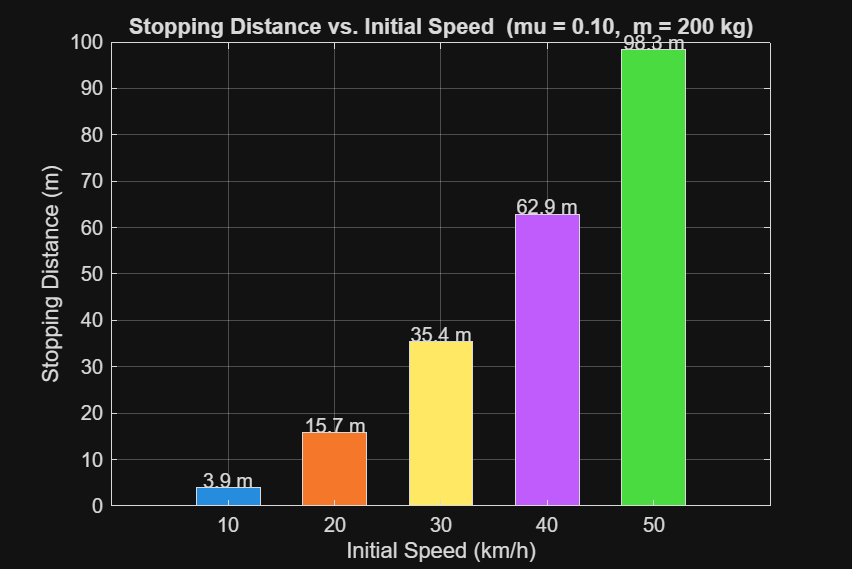


%% -- 4. STOPPING DISTANCE SUMMARY BAR CHART --------------

figure('Name','Stopping Distance Comparison','NumberTitle','off', ...
       'Position',[100 650 600 400]);

bar_h = bar(v0_kmh, stop_dist, 0.6, 'FaceColor', 'flat');
% Build colour matrix dynamically from the current colormap
cmap = lines(num_speeds);
bar_h.CData = cmap;

% Annotate each bar with the stopping distance
for i = 1:num_speeds
    text(v0_kmh(i), stop_dist(i) + 1.5, ...
         sprintf('%.1f m', stop_dist(i)), ...
         'HorizontalAlignment','center','FontSize',10);
end

xlabel('Initial Speed (km/h)');
ylabel('Stopping Distance (m)');
title(sprintf('Stopping Distance vs. Initial Speed  (mu = %.2f,  m = %d kg)', mu, m));
grid on;


%% -- 5. PRINT SUMMARY TABLE TO COMMAND WINDOW -----------

fprintf('\n========================================\n');

fprintf('  Vehicle Braking Distance - Summary\n');

  Vehicle Braking Distance - Summary


fprintf('  mu = %.2f  |  mass = %d kg\n', mu, m);

  mu = 0.10  |  mass = 200 kg


fprintf('========================================\n');

fprintf('  Speed (km/h)  |  Stop dist (m)  |  Stop time (s)\n');

  Speed (km/h)  |  Stop dist (m)  |  Stop time (s)


fprintf('  -------------|-----------------|---------------\n');

  -------------|-----------------|---------------


for i = 1:num_speeds
    fprintf('  %6d       |  %9.2f      |  %8.3f\n', ...
            v0_kmh(i), stop_dist(i), stop_time(i));
end

      10       |       3.93      |     2.832
      20       |      15.73      |     5.664
      30       |      35.39      |     8.495
      40       |      62.92      |    11.327
      50       |      98.32      |    14.158


fprintf('========================================\n\n');


% Verify against analytical solution: d = v0^2 / (2*mu*g)
fprintf('Analytical check (d = v0^2 / 2*mu*g):\n');

Analytical check (d = v0^2 / 2*mu*g):


for i = 1:num_speeds
    d_analytical = (v0(i)^2) / (2 * mu * g);
    fprintf('  %d km/h:  simulated = %.2f m  |  analytical = %.2f m\n', ...
            v0_kmh(i), stop_dist(i), d_analytical);
end

  10 km/h:  simulated = 3.93 m  |  analytical = 3.93 m
  20 km/h:  simulated = 15.73 m  |  analytical = 15.73 m
  30 km/h:  simulated = 35.39 m  |  analytical = 35.39 m
  40 km/h:  simulated = 62.92 m  |  analytical = 62.92 m
  50 km/h:  simulated = 98.32 m  |  analytical = 98.32 m


fprintf('\n');